clear all
close all
clc

A1=2;
A2=2;
A3=2;


L(1) = Link('revolute','d',A1,'alpha',pi/2,'a',0,'offset',0);
L(2) = Link('revolute','d',0,'alpha',-pi/2,'a',0,'offset',-pi/2); %eslabon 2 --> fila 2
L(3) = Link('prismatic','theta',0,'alpha',0,'a',0,'offset',A2);
L(3).qlim = [0 2]; 
L

 
L = 
 theta=q1, d=          2, a=          0, alpha=      1.571, offset=          0 (R,stdDH)
 theta=q2, d=          0, a=          0, alpha=     -1.571, offset=     -1.571 (R,stdDH)
 theta=          0, d=q3, a=          0, alpha=          0, offset=          2 (P,stdDH)



%unir links 'eslabones'
robotesferico = SerialLink(L,'name','Angular')

 
robotesferico = 
 
Angular (3 axis, RRP, stdDH, fastRNE)                            
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          2|          0|      1.571|          0|
|  2|         q2|          0|          0|     -1.571|     -1.571|
|  3|          0|         q3|          0|          0|          2|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


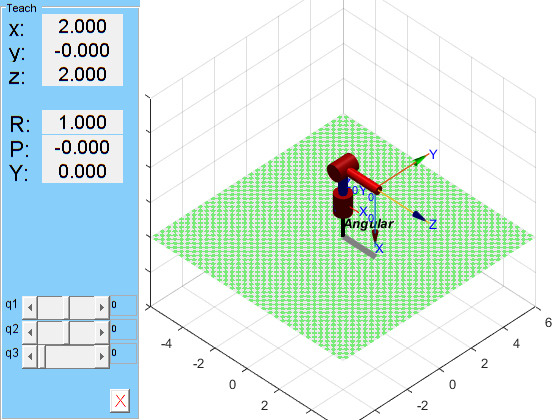


robotesferico.tool = transl(0,0,0);


q = [0 0 0 ];  % Ángulos de las articulaciones

% Define el espacio de trabajo (ajusta los valores según sea necesario)
limites_espacio_trabajo = [-7 7 -7 7 -2 7];

robotesferico.plot(q, 'workspace', limites_espacio_trabajo);

hold on 
trplot(eye(4),'rgb','length',1,'frame','0') % sistema coordenadas de la base 
axis([-6 6 -6 6 -6 6])% ajusta los ejes 
view(45, 40)% vista frente 
robotesferico.teach()


TZ0 = [1 0 0 0; 0 1 0 0; 0 0 1 A1; 0 0 0 1]

TZ0 =      1     0     0     0
     0     1     0     0
     0     0     1     2
     0     0     0     1


RZ0 = [cos(q1) -sin(q1) 0 0; sin(q1) cos(q1) 0 0; 0 0 1 0; 0 0 0 1]

Unrecognized function or variable 'q1'.

TX1 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RX1 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]
T01 =  TZ0*RZ0*TX1*RX1


TZ1 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RZ1 = [cos(-pi/2) -sin(-pi/2) 0 0; sin(-pi/2) cos(-pi/2) 0 0; 0 0 1 0; 0 0 0 1]
TX2 = [1 0 0 A2; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RX2 = [1 0 0 0; 0 cos(pi) -sin(pi) 0; 0 sin(pi) cos(pi) 0; 0 0 0 1]
T12 =  TZ1*RZ1*TX2*RX2


TZ2 = [1 0 A4 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RZ2 = [cos(0) -sin(0) 0 0; sin(0) cos(0) 0 0; 0 0 1 0; 0 0 0 1]
TX3 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]
RX3 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]
T23 =  TZ2*RZ2*TX3*RX3

T03 = T01*T12*T23